% Projeto 8 de Camadas
% Achando os coeficientes do filtro passa baixa

s = tf('s');

% Função de transferência
% Como queremos filtrar as frequências acima de 4000Hz,temos:
f_corte = 2000

f_corte = 2000

wc = 2*pi*f_corte;
G = tf([wc^2], [1 2*wc wc^2])

G =
 
           1.579e08
  ---------------------------
  s^2 + 2.513e04 s + 1.579e08
 
Continuous-time transfer function.
Model Properties


% Período
% Como a frequência de amostragem é de 44100Hz, temos:

T = 1/44100;

% Função do filtro

F = c2d(G,T)

F =
 
   0.03365 z + 0.02783
  ----------------------
  z^2 - 1.504 z + 0.5656
 
Sample time: 2.2676e-05 seconds
Discrete-time transfer function.
Model Properties


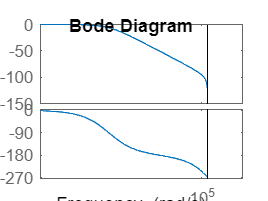

bode(F)